clc
clear

**Kmeans**

a) Generate a 2D uncorrelated Gaussian distributed training dataset

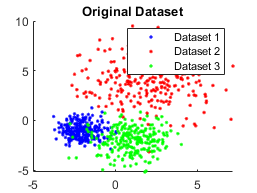

samples = 250;

%cluster 1 
mean1 = [-2; -1];
sd1 = 0.75;

%cluster 2
mean2 = [2; 4];
sd2 = 2;

%cluster 3
mean3 = [1; -2];
sd3 = 1.25;

cluster1 = sd1 * randn(2,samples) + repmat(mean1,1,samples);
cluster2 = sd2 * randn(2,samples) + repmat(mean2,1,samples);
cluster3 = sd3 * randn(2,samples) + repmat(mean3,1,samples);

%plot
hold on
plot(cluster1(1,:),cluster1(2,:),'b.')
plot(cluster2(1,:),cluster2(2,:),'r.')
plot(cluster3(1,:),cluster3(2,:),'g.')
title("Original Dataset")
legend('Dataset 1','Dataset 2','Dataset 3')
hold off

b) Concatenate the datasets into a single dataset and plot all the points

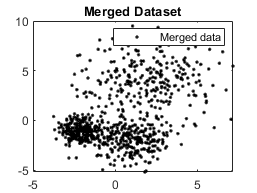

cluster3 = cat(2,cluster1,cluster2,cluster3);

plot(cluster3(1,:),cluster3(2,:),'black.')
title("Merged Dataset")
legend('Merged data')

c) Given the number of clusters as 3, implement Kmeans clustering from first principles

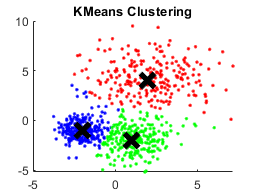

k = 3;
iterations = 750;
%closest = zeros(1,iterations);
%totalDistance = 0;

% calculate the distance between each node to each centroid node
%assign the node to the nearest cluster
figure
hold on
for i  = 1:iterations
    %measure distance from data to centroid 1 and 2. assign near
    %return indicies
   
    dist1 = sqrt((mean1(1,1)-cluster3(1,i))^2+(mean1(2,1)-cluster3(2,i))^2);
    dist2 = sqrt((mean2(1,1)-cluster3(1,i))^2+(mean2(2,1)-cluster3(2,i))^2);
    dist3 = sqrt((mean3(1,1)-cluster3(1,i))^2+(mean3(2,1)-cluster3(2,i))^2);
    
    if dist1 < dist2 && dist1 < dist3
        a = 1;
        plot(cluster3(1,i),cluster3(2,i),'b.')
    elseif (dist2 < dist3 && dist2 <dist1)
        a = 2;
        plot(cluster3(1,i),cluster3(2,i),'r.')
    else
        a = 3;
        plot(cluster3(1,i),cluster3(2,i),'g.')
    end
%    closest(1,i) = a;

end
%totalDistance
%closest;
title("KMeans Clustering")
plot(mean1(1,1),mean1(2,1),'black x','MarkerSize',15, 'linewidth',4)
plot(mean2(1,1),mean2(2,1),'black x','MarkerSize',15,'linewidth',4)
plot(mean3(1,1),mean3(2,1),'black x','MarkerSize',15,'linewidth',4)

hold off

%legend('Cluster1','Cluster2','Cluster3','Centroid')

